# Project 3: Trajectory Generation Prelab

tic
%Part A
close all;
clc;
clear all;

%Fixed Values

f_cn=200;               %mm/s
An=1000;                 %and deceleration (-D) mm/s^2
Ti=0.1e-3;                  %interpolation time: 0.1ms

%P1 to P2: Math
P1=[0 0];                   %x and y locations of staring point 1
P2=[40 30];                 %x and y locations of starting point 2 

[s, ~]=sumsqr(P2);       %length of P1 to P2 mm
L=sqrt(s);

%time estimate
T1=f_cn/An;          %Increasing feedrate time
T3=T1;                      %Decreasing feedrate time
T2=(L/f_cn)-f_cn/An;   %constant speed time

%re-evaluate Counts
N1=ceil(T1/Ti);
N2=ceil(T2/Ti);
N3=ceil(T3/Ti);

%times
T1_prime=N1*Ti;
T2_prime=N2*Ti;
T3_prime=N3*Ti;


%re-evaluate speeds
f_cn=2*L/(T1_prime+2*T2_prime+T3_prime);
An=f_cn/T1_prime;

%compute times
tau1=Ti*(0:N1);
tau2=Ti*(1:N2);
tau3=Ti*(1:N3);

%compute trajectories
l1=0.5*An*(tau1.^2);
l1n=l1(end);

l2=l1n+f_cn*tau2;
l2n=l2(end);
l3=l2n+f_cn*tau3-0.5*An*(tau3.^2);

%combine trajectories
l=horzcat(l1,l2,l3);
s1=[l*P2(1)/sqrt(sumsqr(P2)) ; l*P2(2)/sqrt(sumsqr(P2))];

%P2 to P3 Math

f_cn=200;               %mm/s
An=1000;                 %and deceleration (-D) mm/s^2
Ti=0.1e-3;                  %interpolation time: 0.1ms


L=20;

%T2 is negative so use a modified trajectorys
f_cm=sqrt(An*L);

%Evaluate times and counts
T1=f_cm/An;          %Increasing feedrate time
T3=T1;                      %Decreasing feedrate time

N1=ceil(T1/Ti);
N3=ceil(T3/Ti);

T1_prime=N1*Ti;
T3_prime=N3*Ti;

%recalc f abd
f_cnm=L/T1_prime;
An=f_cnm/T1_prime;

%Evaluate Times
tau1=Ti*(0:N1);
tau3=Ti*(1:N3);

%Compute Trajectory
l1=0.5*An*(tau1.^2);
l1n=l1(end);
l3=l1n+f_cnm*tau3-0.5*An*(tau3.^2);

l=horzcat(l1,l3);
sStart=+s1(:,end);
s2=[l; zeros(1,length(l))]+sStart;


%P3 to P4 Math

f_cn=200;
An=1000;
Circle_centre=[90; 30];
R=30;
L=2*pi*R;

%Estimate Time
T1=f_cn/An;
T3=T1;
T2=L/f_cn-f_cn/An;

%intervals
N1=ceil(T1/Ti);
N2=ceil(T2/Ti);
N3=ceil(T3/Ti);

%integer times
T1_prime=N1*Ti;
T2_prime=N2*Ti;
T3_prime=N3*Ti;

%recalc speeds
f_cn=2*L/(T1_prime+2*T2_prime+T3_prime);
An=f_cn/T1_prime;

%generate times
tau1=Ti*(0:N1);
tau2=Ti*(1:N2);
tau3=Ti*(1:N3);

%generate displacement trajectories
l1=0.5*An*tau1.^2;
l1n=l1(end);
l2=l1n+f_cn*tau2;
l2n=l2(end);
l3=l2n+f_cn*tau3-0.5*An*tau3.^2;


l=horzcat(l1,l2,l3);
theta=2*pi*l/l(end);
s3=Circle_centre+R*[-cos(theta);-sin(theta)]; %[x_circ ; y_circ];

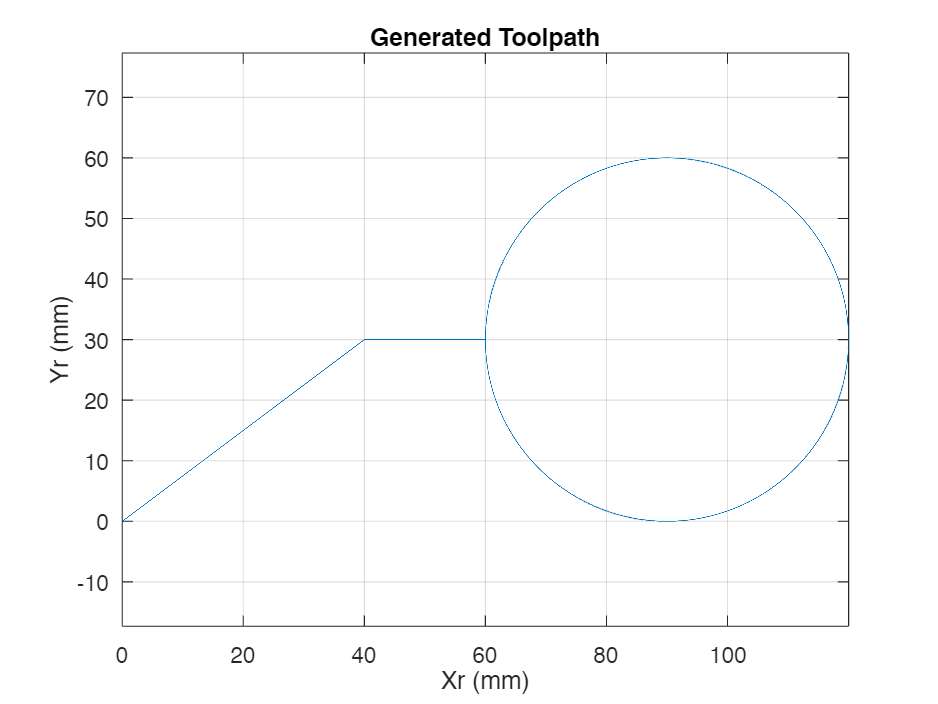

%A1
sr=horzcat(s1,s2,s3);

trajSample.t=Ti*(0:(length(sr)-1))';
trajSample.x=sr(1,:)';
trajSample.y=sr(2,:)';


plot(sr(1,:),sr(2,:));
title("Generated Toolpath");
xlabel("Xr (mm)");
ylabel("Yr (mm)");
axis equal;
grid on;

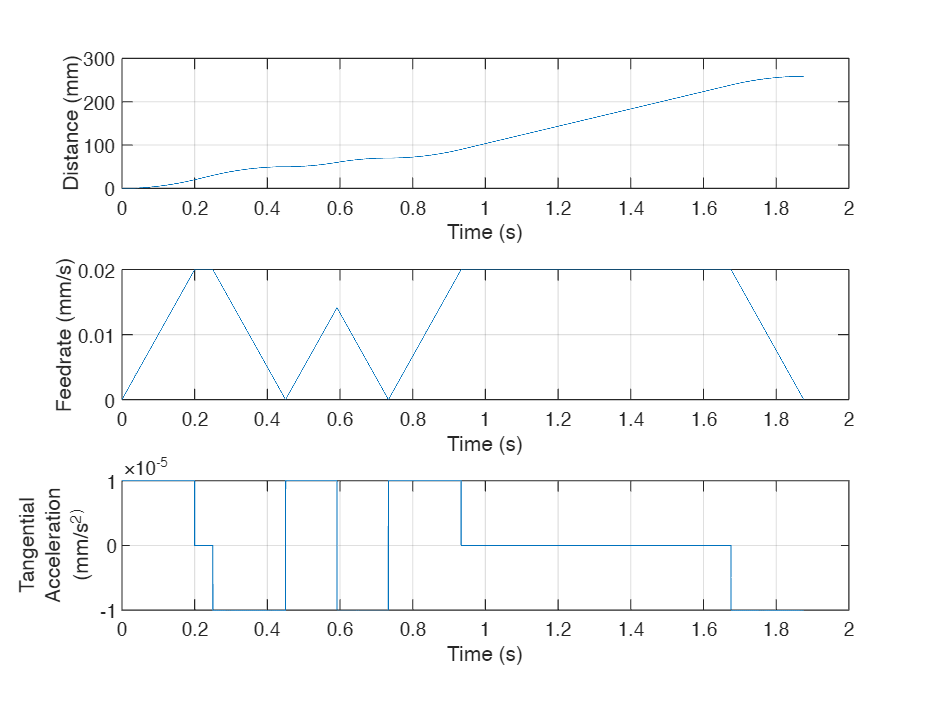

%A2
feedrate=vecnorm(diff(sr,1,2));
distance=cumsum(feedrate);
tan_accel=diff(feedrate);

subplot(3, 1, 1);
plot((1:length(distance)) * Ti, distance);
ylabel('Distance (mm)');
xlabel('Time (s)');
grid on;

subplot(3, 1, 2);
plot((1:length(feedrate)) * Ti, feedrate);
ylabel('Feedrate (mm/s)');
xlabel('Time (s)');
grid on;

subplot(3, 1, 3);
plot((1:length(tan_accel)) * Ti, tan_accel);
ylabel({'Tangential', 'Acceleration', '(mm/s^2)'});
xlabel('Time (s)');
grid on;

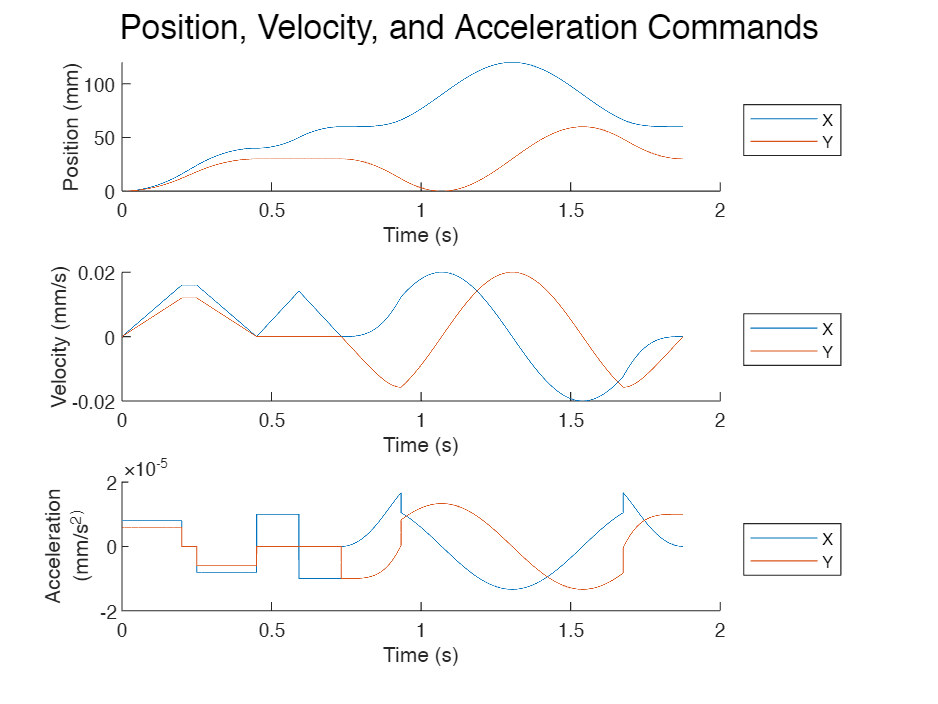

%A3
sr_dot = diff(sr, 1, 2);
sr_ddot = diff(sr_dot, 1, 2);

clf
subplot(3, 1, 1)
hold on
plot((1:length(sr)) * Ti, sr(1,:))
plot((1:length(sr)) * Ti, sr(2,:))
ylabel('Position (mm)')
xlabel('Time (s)')
legend('X', 'Y', 'Location', 'eastoutside')

subplot(3, 1, 2)
hold on
plot((1:length(sr_dot)) * Ti, sr_dot(1,:))
plot((1:length(sr_dot)) * Ti, sr_dot(2,:))
ylabel('Velocity (mm/s)')
xlabel('Time (s)')
legend('X', 'Y', 'Location', 'eastoutside')

subplot(3, 1, 3)
hold on
plot((1:length(sr_ddot)) * Ti, sr_ddot(1,:))
plot((1:length(sr_ddot)) * Ti, sr_ddot(2,:))
ylabel({'Acceleration', '(mm/s^2)'})
xlabel('Time (s)')
legend('X', 'Y', 'Location', 'eastoutside')
sgtitle('Position, Velocity, and Acceleration Commands')

% Part B
s = tf('s');
Ka_x = 1;
Kt_x = 0.49;
Ke_x = 1.59;
Je_x = 4.36e-4;
B_x = 0.0094;

Ka_y = 1;
Kt_y = 0.49;
Ke_y = 1.59;
Je_y = 3e-4;
B_y = 0.0091;
G_x = Ka_x * Kt_x * (1 / (Je_x * s + B_x)) * (1 / s) * Ke_x;
G_y = Ka_y * Kt_y * (1 / (Je_y * s + B_y)) * (1 / s) * Ke_y;


Ke=Ke_x; %x=y
Ka=Ka_x;
Kt=Ka_y;


%x axis open loop
O_lo_x=ol_controller_design( G_x, B_x/Je_x, 20, 60) %xaxis, 20Hz, 60deg Phase margin

O_lo_x = struct with fields:
            K: 3.2400
    Magnitude: 1.0000
        Phase: -120.0000
        Alpha: 7.6583
            T: 0.0029
          LLI: [1×1 tf]


O_hi_x=ol_controller_design( G_x, B_x/Je_x, 40, 60) %xaxis, 40Hz, 60deg Phase margin

O_hi_x = struct with fields:
            K: 11.1533
    Magnitude: 1
        Phase: -120.0000
        Alpha: 10.1186
            T: 0.0013
          LLI: [1×1 tf]




%plot OL tf and controller tf
figure()
ol_x_lbw = minreal(O_lo_x.LLI * G_x);
ol_x_hbw = minreal(O_hi_x.LLI * G_x);
bode(ol_x_lbw, ol_x_hbw)
legend("Open Loop", "LLI LBW", "LLI HBW",Location="southeast");

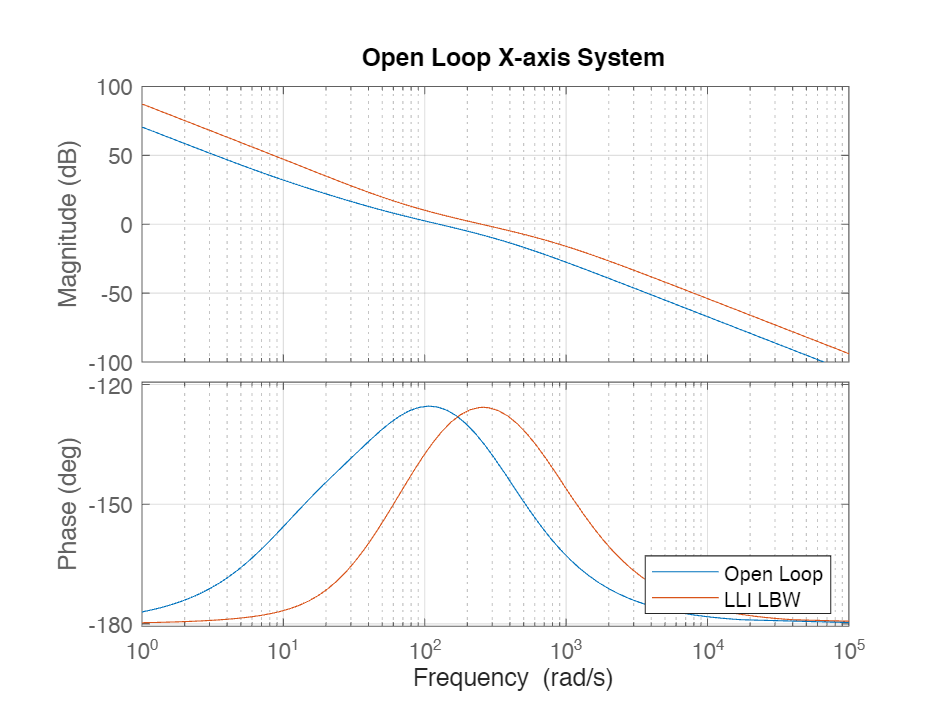

title("Open Loop X-axis System");
grid on
hold off;

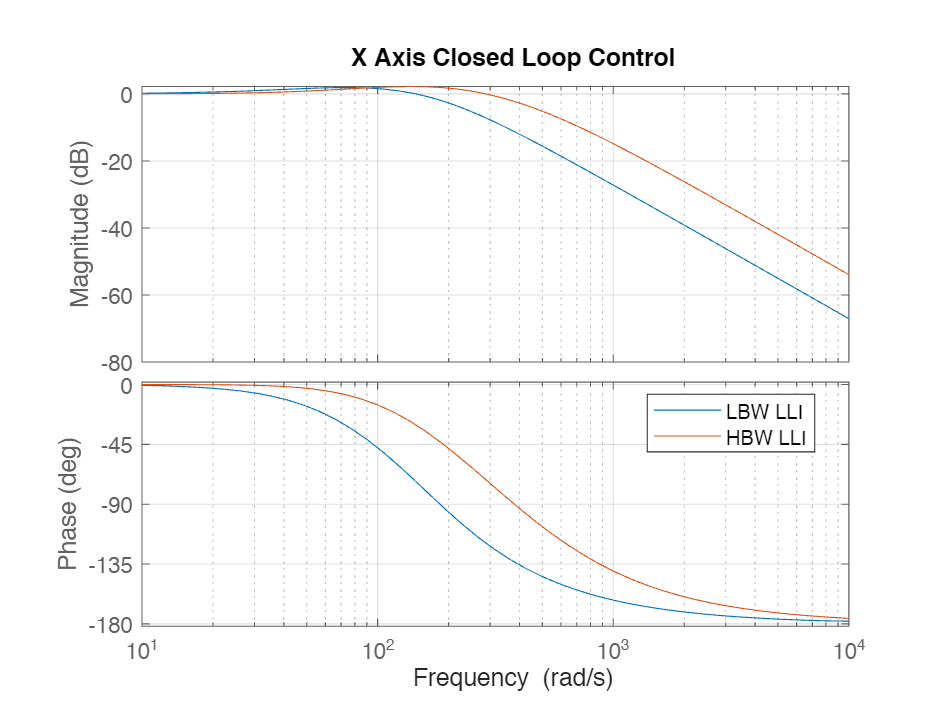


%x axis closed loop
cl_x_lbw = feedback(ol_x_lbw, 1);
cl_x_hbw = feedback(ol_x_hbw, 1);
figure();
bode(cl_x_lbw, cl_x_hbw);
legend("LBW LLI", "HBW LLI",Location="best");
title("X Axis Closed Loop Control");
grid on;



%LBW is in index 1, HBW is index 2
[Description_discrete_lo_x, Description_continuous_lo_x]=controller_description(cl_x_lbw, G_x, Ti)

Description_discrete_lo_x = struct with fields:
    Overshoot: 58.9337
     Risetime: 0.0263
        Poles: [6×1 double]
        Zeros: [5×1 double]
    Bandwidth: Inf
          LTI: [1×1 tf]


Description_continuous_lo_x = struct with fields:
    Overshoot: 22.1097
     Risetime: 0.0091
        Poles: [4×1 double]
        Zeros: [2×1 double]
    Bandwidth: 206.1193


[Description_discrete_hi_x, Description_continuous_hi_x]=controller_description(cl_x_hbw, G_x, Ti)

Description_discrete_hi_x = struct with fields:
    Overshoot: 49.3799
     Risetime: 0.0263
        Poles: [6×1 double]
        Zeros: [5×1 double]
    Bandwidth: Inf
          LTI: [1×1 tf]


Description_continuous_hi_x = struct with fields:
    Overshoot: 24.1271
     Risetime: 0.0045
        Poles: [4×1 double]
        Zeros: [2×1 double]
    Bandwidth: 411.4164


%x axis open loop
O_lo_y=ol_controller_design( G_y, B_y/Je_y, 20, 60) %xaxis, 20Hz, 60deg Phase margin

O_lo_y = struct with fields:
            K: 2.5001
    Magnitude: 1
        Phase: -120.0000
        Alpha: 6.2602
            T: 0.0032
          LLI: [1×1 tf]


O_hi_y=ol_controller_design( G_y, B_y/Je_y, 40, 60) %xaxis, 40Hz, 60deg Phase margin

O_hi_y = struct with fields:
            K: 8.1692
    Magnitude: 1
        Phase: -120.0000
        Alpha: 8.9937
            T: 0.0013
          LLI: [1×1 tf]




%plot OL tf and controller tf
ol_y_lbw = minreal(O_lo_y.LLI * G_y);
ol_y_hbw = minreal(O_hi_y.LLI * G_y);
figure();
bode(ol_y_lbw, ol_y_hbw)
legend("Open Loop", "LLI LBW", "LLI HBW",Location="southeast");

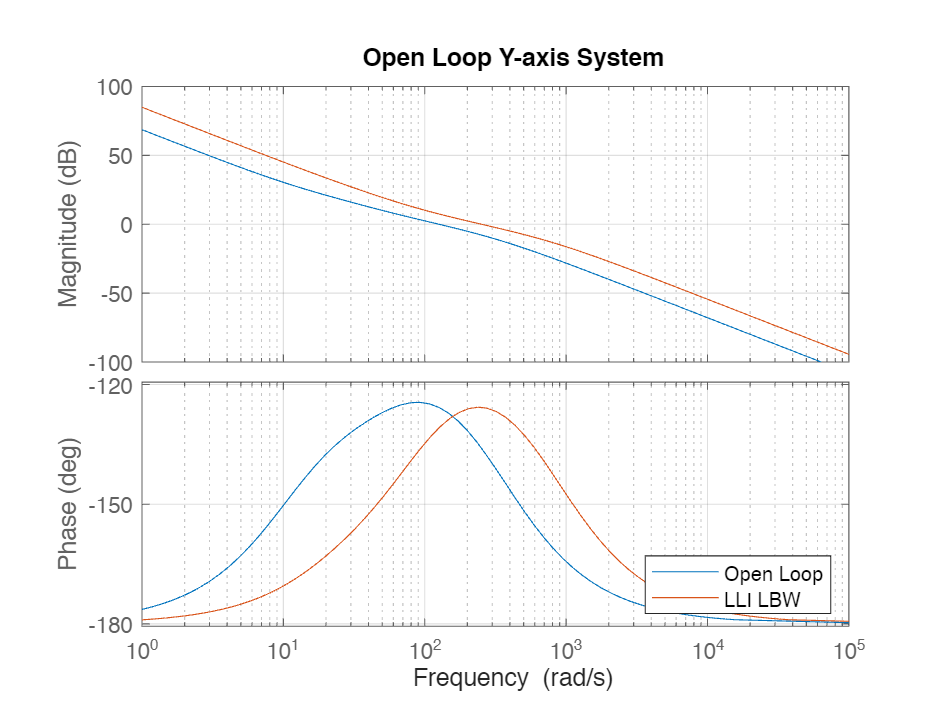

title("Open Loop Y-axis System");
grid on
hold off;

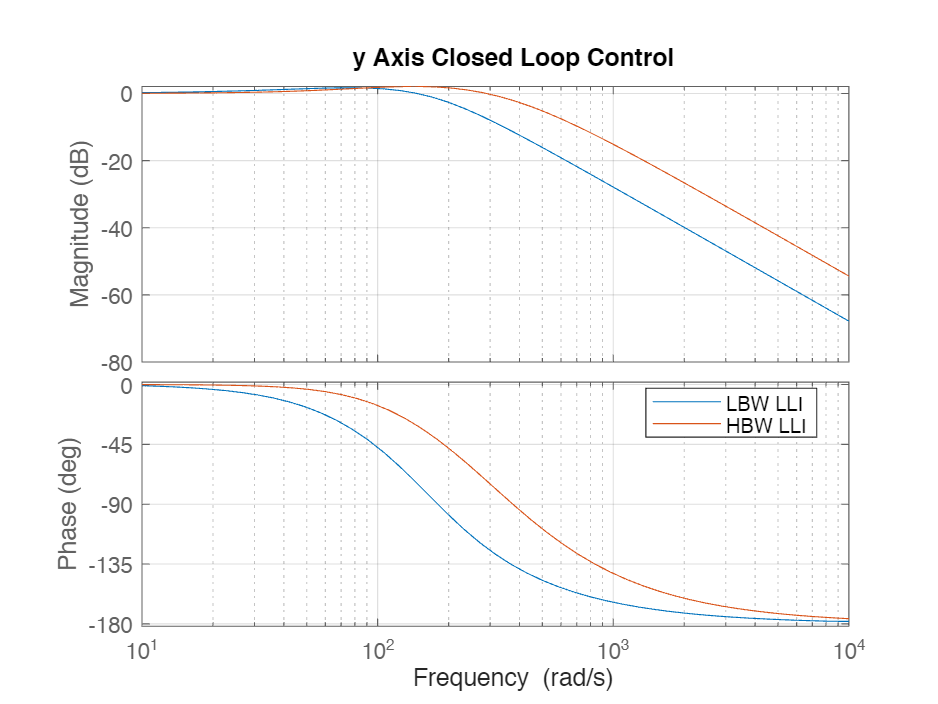


%closed loop
cl_y_lbw = feedback(ol_y_lbw, 1);
cl_y_hbw = feedback(ol_y_hbw, 1);
bode(cl_y_lbw, cl_y_hbw);
legend("LBW LLI", "HBW LLI",Location="best");
title("y Axis Closed Loop Control");
grid on;



%LBW is in index 1, HBW is index 2
[Description_discrete_lo_y, Description_continuous_lo_y]=controller_description(cl_y_lbw, G_y, Ti)

Description_discrete_lo_y = struct with fields:
    Overshoot: 67.7523
     Risetime: 0.0218
        Poles: [6×1 double]
        Zeros: [5×1 double]
    Bandwidth: Inf
          LTI: [1×1 tf]


Description_continuous_lo_y = struct with fields:
    Overshoot: 20.9033
     Risetime: 0.0093
        Poles: [4×1 double]
        Zeros: [2×1 double]
    Bandwidth: 206.3840


[Description_discrete_hi_y, Description_continuous_hi_y]=controller_description(cl_y_hbw, G_y, Ti)

Description_discrete_hi_y = struct with fields:
    Overshoot: 45.5945
     Risetime: 0.0222
        Poles: [6×1 double]
        Zeros: [5×1 double]
    Bandwidth: Inf
          LTI: [1×1 tf]


Description_continuous_hi_y = struct with fields:
    Overshoot: 23.2344
     Risetime: 0.0045
        Poles: [4×1 double]
        Zeros: [2×1 double]
    Bandwidth: 411.7778


%Pole placement time






%Part C.1: Default Trajectory
contx_z = Description_discrete_lo_x.LTI; 
conty_z =Description_discrete_lo_y.LTI; 

traj_t = Ti * (0:(length(sr) - 1))';
traj_x = sr(1, :)';
traj_y = sr(2, :)';
simout = sim("C:\Users\Lachlan Reynolds\Desktop\Past Years\Year 4\Term 1\MECH 467\Labs\controller_sim0x2810x291.slx").simout.Data;






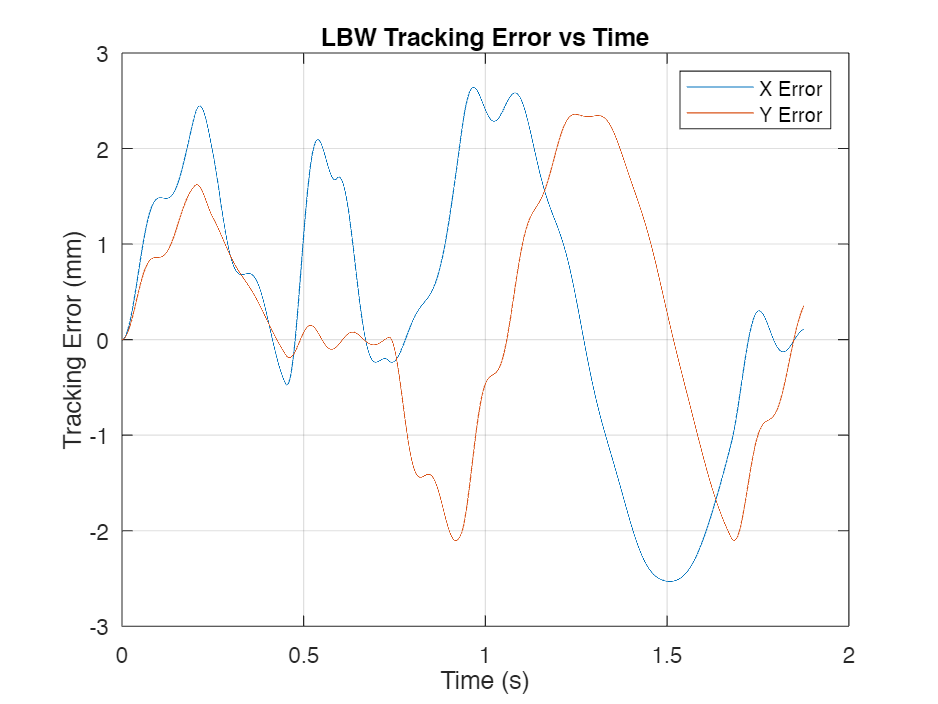

%Part E: 
% E.1 Plot tracking error over time

time=simout(:,1);
position_command_x.lbw=simout(:,2);
simulated_position_x.lbw=simout(:,3);
position_command_y.lbw=simout(:,4);
simulated_position_y.lbw=simout(:,5);

tracking_error_x.lbw=position_command_x.lbw-simulated_position_x.lbw;
tracking_error_y.lbw=position_command_y.lbw-simulated_position_y.lbw;

figure()
plot(time,tracking_error_x.lbw);
hold on;
plot(time, tracking_error_y.lbw);
hold off;
xlabel("Time (s)");
ylabel("Tracking Error (mm)");
title("LBW Tracking Error vs Time");
grid on;
legend("X Error", "Y Error");

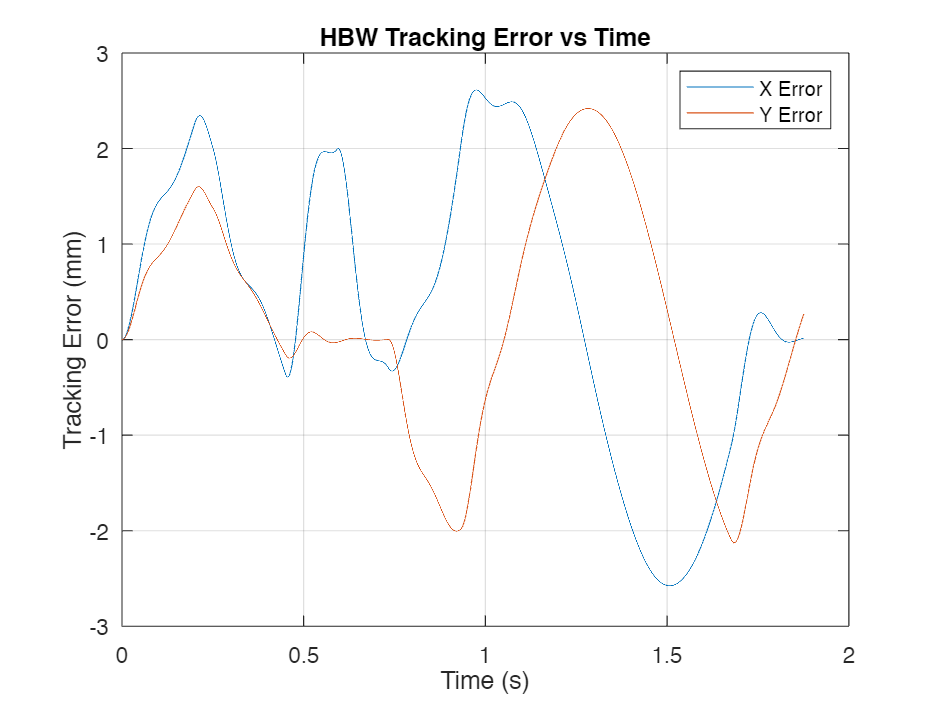



% HBW controllers
contx_z = Description_discrete_hi_x.LTI; 
conty_z =Description_discrete_hi_y.LTI; 

traj_t = Ti * (0:(length(sr) - 1))';
traj_x = sr(1, :)';
traj_y = sr(2, :)';
simout = sim("C:\Users\Lachlan Reynolds\Desktop\Past Years\Year 4\Term 1\MECH 467\controller_sim.slx").simout.Data;


time=simout(:,1);
time_lbw=time;
position_command_x.hbw=simout(:,2);
simulated_position_x.hbw=simout(:,3);
position_command_y.hbw=simout(:,4);
simulated_position_y.hbw=simout(:,5);

tracking_error_x.hbw=position_command_x.hbw-simulated_position_x.hbw;
tracking_error_y.hbw=position_command_y.hbw-simulated_position_y.hbw;

figure();
plot(time,tracking_error_x.hbw);
hold on;
plot(time, tracking_error_y.hbw);
hold off;
xlabel("Time (s)");
ylabel("Tracking Error (mm)");
grid on;
title("HBW Tracking Error vs Time");
legend("X Error", "Y Error");

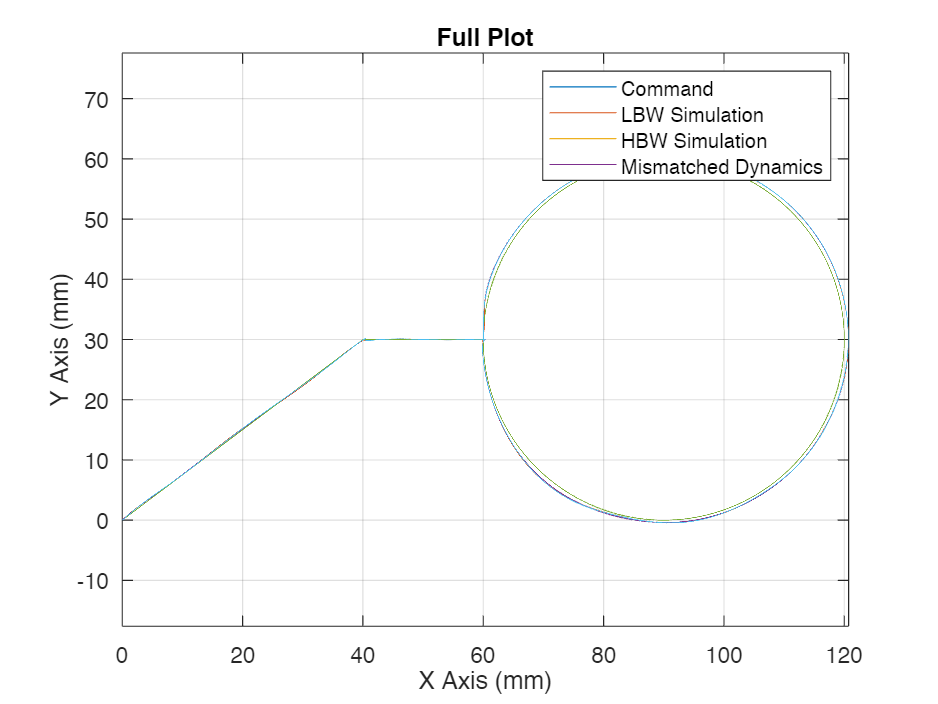


%E.2: Trajectories

%Full Plot
plot(position_command_x.lbw,position_command_y.lbw);    %LBW x and y traj
hold on;
plot(simulated_position_x.lbw, simulated_position_y.lbw); %LBW x and y sim
hold on;
plot(position_command_x.hbw,position_command_y.hbw); %HBW x and y traj
hold on;
plot(simulated_position_x.hbw, simulated_position_y.hbw); %LBW x and y sim
hold on;
plot(position_command_x.hbw,position_command_y.lbw); %HBW x and LBW y traj
hold on;
plot(simulated_position_x.hbw, simulated_position_y.lbw); %HBW x and LBW y sim
hold off;
axis equal;
xlabel("X Axis (mm)");
ylabel("Y Axis (mm)");
grid on;
legend("Command", "LBW Simulation", "HBW Simulation", "Mismatched Dynamics");
title("Full Plot");

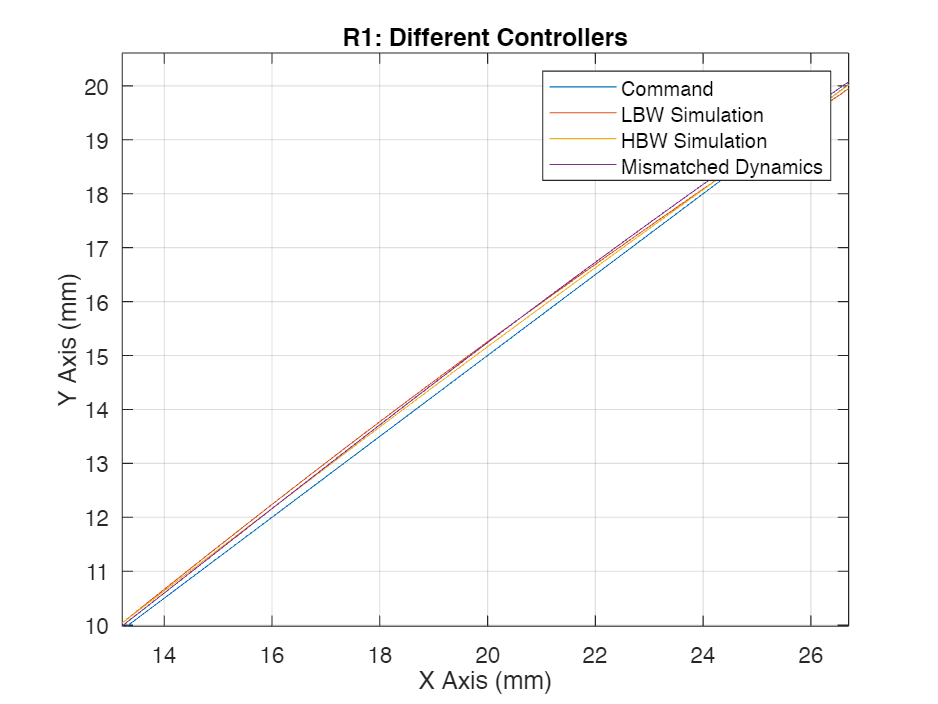

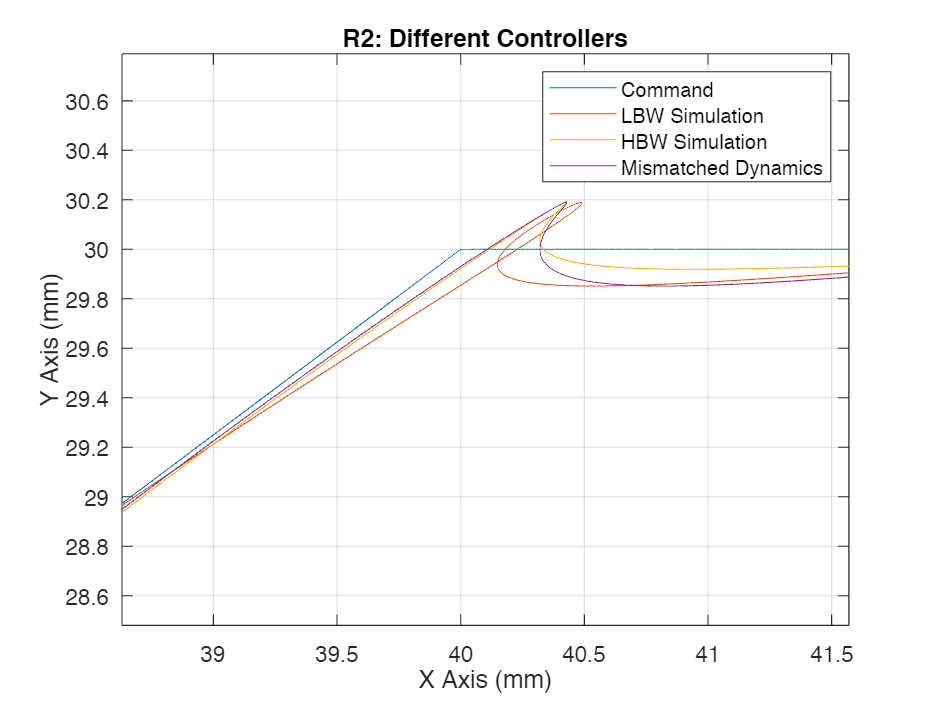

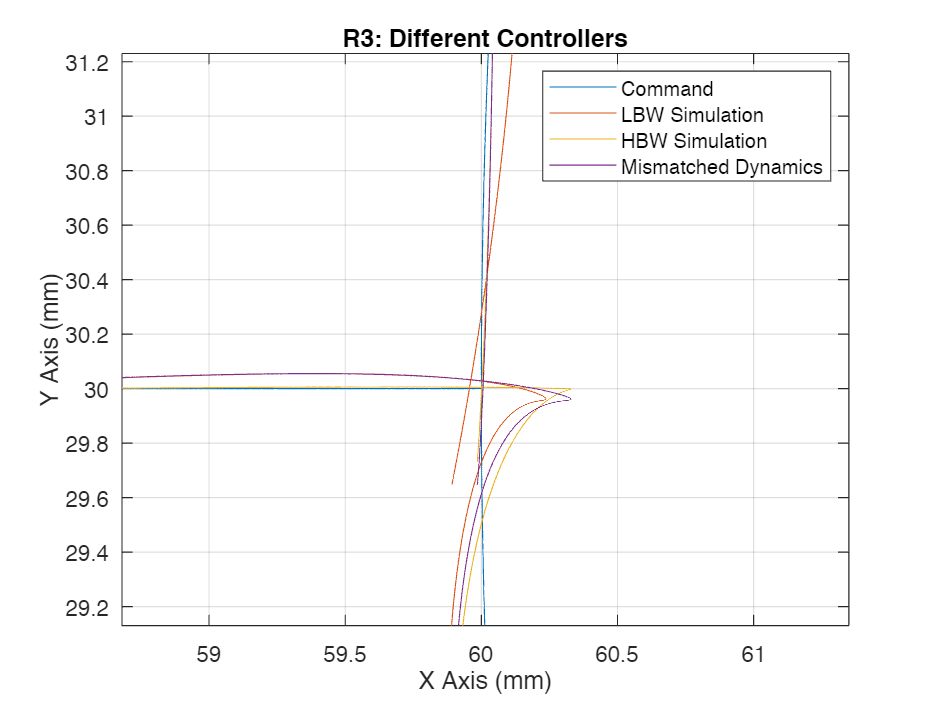

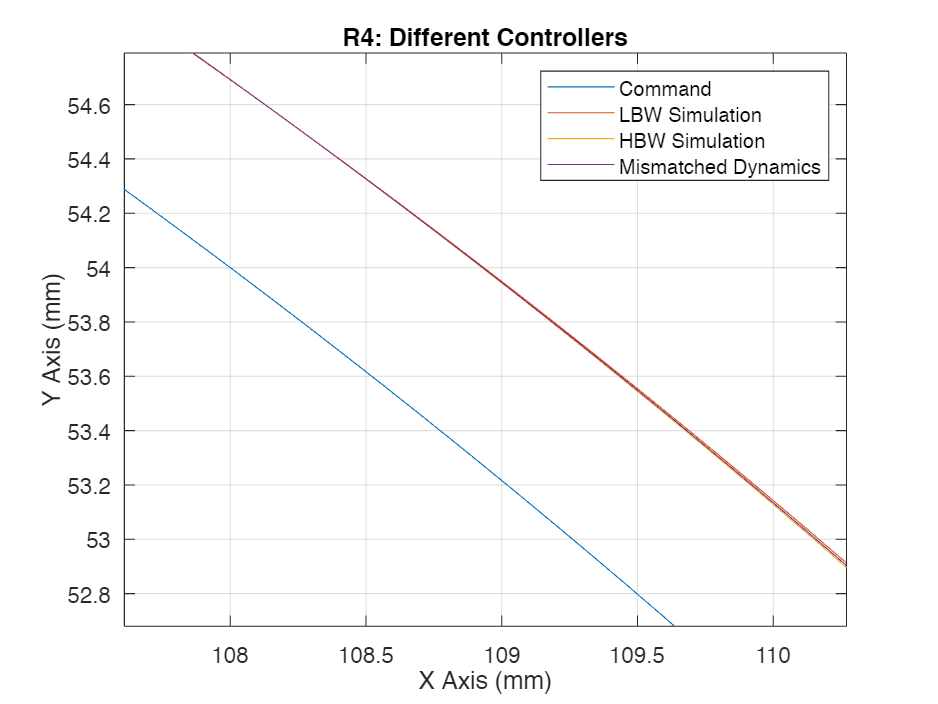


%X and Y limits for R1-R4
xlims=[13.22, 26.70 ; 38.63, 41.57 ; 58.68, 61.35; 107.61, 110.27]; 
ylims=[9.98, 20.61; 28.48, 30.79; 29.13, 31.23; 52.68, 54.79];



%position command indep of controller config
for i=1:4
    
    figure();
    plot(position_command_x.lbw,position_command_y.lbw);    % x and y traj
    hold on;
    plot(simulated_position_x.lbw, simulated_position_y.lbw); %LBW x and y sim
    hold on;
    plot(simulated_position_x.hbw, simulated_position_y.hbw); %LBW x and y sim
    hold on;
    plot(simulated_position_x.hbw, simulated_position_y.lbw); %HBW x and LBW y sim
    hold off;
    axis equal;
    
    xlabel("X Axis (mm)");
    ylabel("Y Axis (mm)");
    grid on;
    
    legend("Command", "LBW Simulation", "HBW Simulation", "Mismatched Dynamics");
    xlim(xlims(i,:));
    ylim(ylims(i,:));
    title(strcat("R", num2str(i), ": Different Controllers"));
end



%E3: analytical tracking error
z=tf('z', Ti);
G_x_d=c2d(G_x, Ti, 'zoh');
C_x_d=Description_discrete_lo_x.LTI;
Gcl_x=C_x_d*G_x_d/1+G_x_d*C_x_d;
x_r_d=Ti*z^-1/(1-1/z)^2;

F_x_d=(1-1/z)*x_r_d*(1-Gcl_x)

F_x_d =
 
  0.0001 z^15 - 0.001292 z^14 + 0.007707 z^13 - 0.02809 z^12 + 0.0698 z^11 - 0.1249 z^10 + 0.1655 z^9 - 0.1645 z^8 + 0.1227 z^7 - 0.06773 z^6 + 0.02693 z^5 - 0.007301 z^4 + 0.00121 z^3 - 9.248e-05 z^2
  ------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
               z^16 - 13.92 z^15 + 89.99 z^14 - 358 z^13 + 978.9 z^12 - 1947 z^11 + 2904 z^10 - 3301 z^9 + 2872 z^8 - 1904 z^7 + 946.7 z^6 - 342.3 z^5 + 85.1 z^4 - 13.02 z^3 + 0.9248 z^2
 
Sample time: 0.0001 seconds
Discrete-time transfer function.




% Define the value for z
z_value = 1; 


% Substitute the value for z
e_x_ss=160*evalfr(F_x_d,z_value)

e_x_ss = 0.0172


%repeat for y
G_y_d=c2d(G_y, Ti, 'zoh');
C_y_d=Description_discrete_lo_y.LTI;
Gcl_y=C_y_d*G_x_d/1+G_y_d*C_y_d;
y_r_d=Ti*z^-1/(1-1/z)^2;

F_y_d=(1-1/z)*y_r_d*(1-Gcl_y)

F_y_d =
 
  0.0001 z^15 - 0.001293 z^14 + 0.007712 z^13 - 0.02811 z^12 + 0.06989 z^11 - 0.1251 z^10 + 0.1658 z^9 - 0.1649 z^8 + 0.123 z^7 - 0.06792 z^6 + 0.02701 z^5 - 0.007326 z^4 + 0.001214 z^3 - 9.285e-05 z^2
  -------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
                z^16 - 13.93 z^15 + 90.04 z^14 - 358.3 z^13 + 980 z^12 - 1950 z^11 + 2909 z^10 - 3307 z^9 + 2878 z^8 - 1909 z^7 + 949.4 z^6 - 343.4 z^5 + 85.4 z^4 - 13.07 z^3 + 0.9285 z^2
 
Sample time: 0.0001 seconds
Discrete-time transfer function.




% Define the value for z
z_value = 1; 


% Substitute the value for z
e_y_ss=120*evalfr(F_y_d,z_value)

e_y_ss = -0.1274


e_ss=sqrt(e_x_ss^2+e_y_ss^2);

%Part F: Effect of Feedrate
f_cn=250;               %mm/s
An=1000;                 %and deceleration (-D) mm/s^2
Ti=0.1e-3;                  %interpolation time: 0.1ms

%P1 to P2: Math
P1=[0 0];                   %x and y locations of staring point 1
P2=[40 30];                 %x and y locations of starting point 2 

[s, ~]=sumsqr(P2);       %length of P1 to P2 mm
L=sqrt(s);

%T2 is negative so use a modified trajectorys
f_cm=sqrt(An*L);

%Evaluate times and counts
T1=f_cm/An;          %Increasing feedrate time
T3=T1;                      %Decreasing feedrate time

N1=ceil(T1/Ti);
N3=ceil(T3/Ti);

T1_prime=N1*Ti;
T3_prime=N3*Ti;

%recalc f abd
f_cnm=L/T1_prime;
An=f_cnm/T1_prime;

%Evaluate Times
tau1=Ti*(0:N1);
tau3=Ti*(1:N3);

%Compute Trajectory
l1=0.5*An*(tau1.^2);
l1n=l1(end);
l3=l1n+f_cnm*tau3-0.5*An*(tau3.^2);

l=horzcat(l1,l3);
s1=[l*P2(1)/sqrt(sumsqr(P2)) ; l*P2(2)/sqrt(sumsqr(P2))];

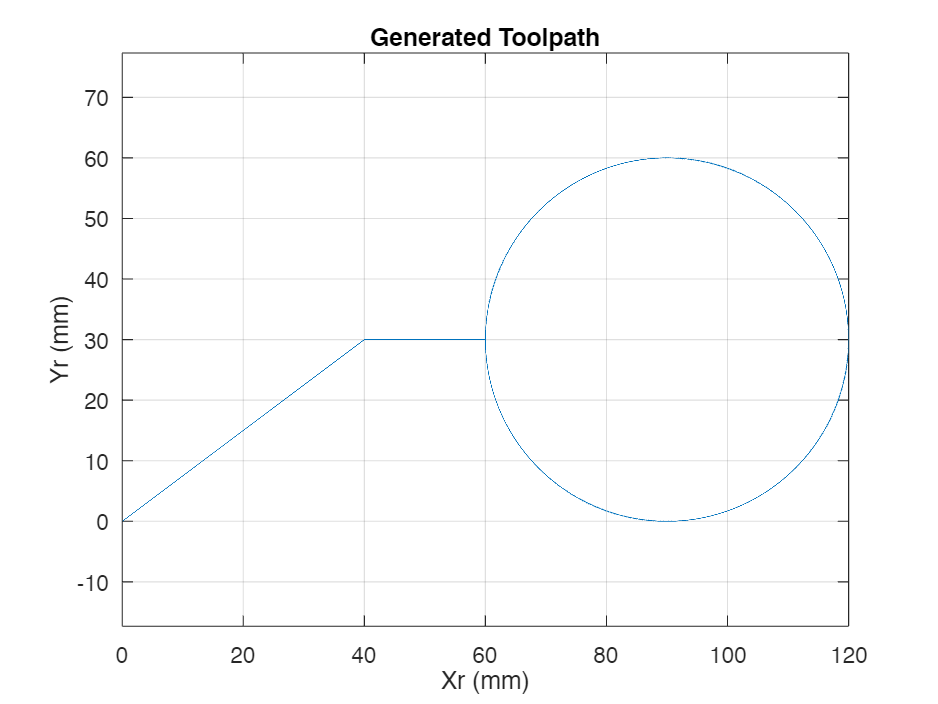

%P2 to P3 Math

f_cn=250;               %mm/s
An=1000;                 %and deceleration (-D) mm/s^2
Ti=0.1e-3;                  %interpolation time: 0.1ms


L=20;

%T2 is negative so use a modified trajectorys
f_cm=sqrt(An*L);

%Evaluate times and counts
T1=f_cm/An;          %Increasing feedrate time
T3=T1;                      %Decreasing feedrate time

N1=ceil(T1/Ti);
N3=ceil(T3/Ti);

T1_prime=N1*Ti;
T3_prime=N3*Ti;

%recalc f abd
f_cnm=L/T1_prime;
An=f_cnm/T1_prime;

%Evaluate Times
tau1=Ti*(0:N1);
tau3=Ti*(1:N3);

%Compute Trajectory
l1=0.5*An*(tau1.^2);
l1n=l1(end);
l3=l1n+f_cnm*tau3-0.5*An*(tau3.^2);

l=horzcat(l1,l3);
sStart=+s1(:,end);
s2=[l; zeros(1,length(l))]+sStart;

%P3 to P4 Math
f_cn=250;
An=1000;
Circle_centre=[90; 30];
R=30;
L=2*pi*R;

%Estimate Time
T1=f_cn/An;
T3=T1;
T2=L/f_cn-f_cn/An;

%intervals
N1=ceil(T1/Ti);
N2=ceil(T2/Ti);
N3=ceil(T3/Ti);

%integer times
T1_prime=N1*Ti;
T2_prime=N2*Ti;
T3_prime=N3*Ti;

%recalc speeds
f_cn=2*L/(T1_prime+2*T2_prime+T3_prime);
An=f_cn/T1_prime;

%generate times
tau1=Ti*(0:N1);
tau2=Ti*(1:N2);
tau3=Ti*(1:N3);

%generate displacement trajectories
l1=0.5*An*tau1.^2;
l1n=l1(end);
l2=l1n+f_cn*tau2;
l2n=l2(end);
l3=l2n+f_cn*tau3-0.5*An*tau3.^2;

l=horzcat(l1,l2,l3);
theta=2*pi*l/l(end);
s3=Circle_centre+R*[-cos(theta);-sin(theta)]; %[x_circ ; y_circ];

sr=horzcat(s1,s2,s3);

trajSample.t=Ti*(0:(length(sr)-1))';
trajSample.x=sr(1,:)';
trajSample.y=sr(2,:)';


plot(sr(1,:),sr(2,:));
title("Generated Toolpath");
xlabel("Xr (mm)");
ylabel("Yr (mm)");
axis equal;
grid on;

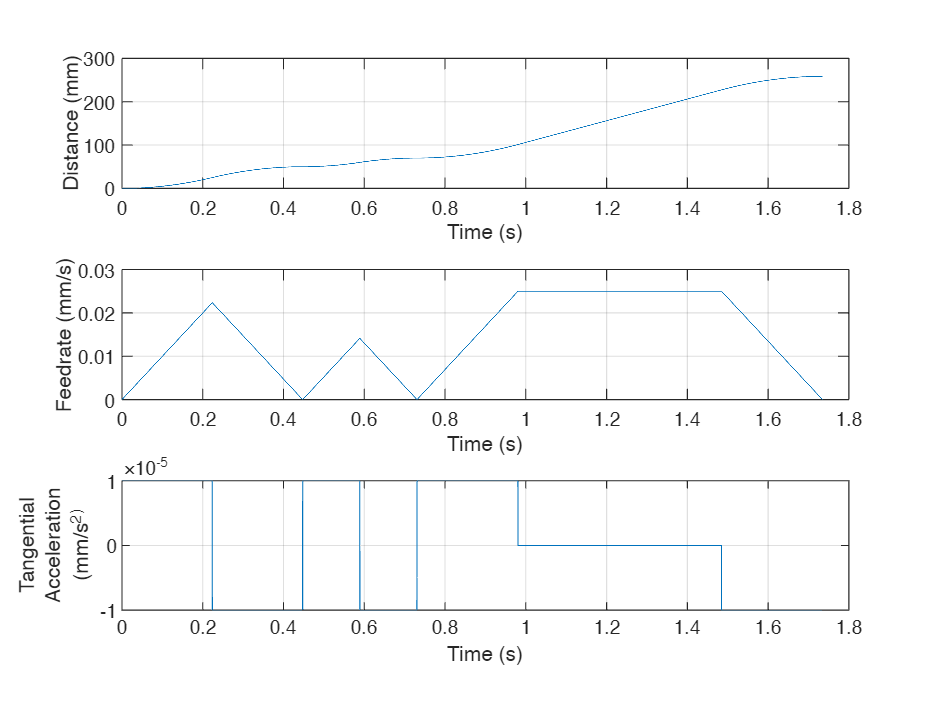


feedrate=vecnorm(diff(sr,1,2));
distance=cumsum(feedrate);
tan_accel=diff(feedrate);

subplot(3, 1, 1);
plot((1:length(distance)) * Ti, distance);
ylabel('Distance (mm)');
xlabel('Time (s)');
grid on;

subplot(3, 1, 2);
plot((1:length(feedrate)) * Ti, feedrate);
ylabel('Feedrate (mm/s)');
xlabel('Time (s)');
grid on;

subplot(3, 1, 3);
plot((1:length(tan_accel)) * Ti, tan_accel);
ylabel({'Tangential', 'Acceleration', '(mm/s^2)'});
xlabel('Time (s)');
grid on;

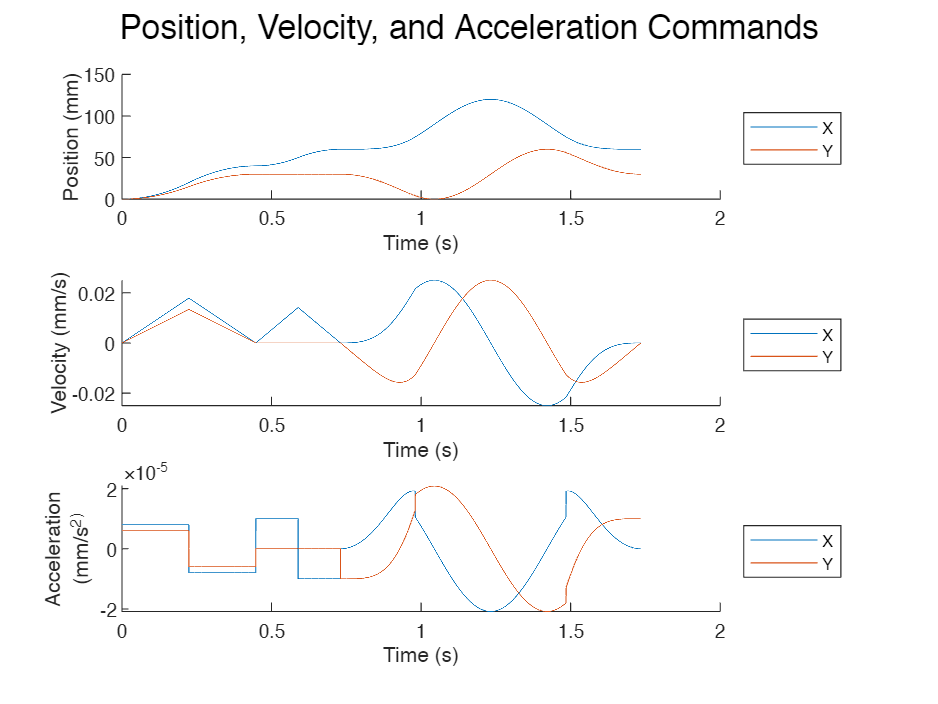


sr_dot = diff(sr, 1, 2);
sr_ddot = diff(sr_dot, 1, 2);

clf
subplot(3, 1, 1)
hold on
plot((1:length(sr)) * Ti, sr(1,:))
plot((1:length(sr)) * Ti, sr(2,:))
ylabel('Position (mm)')
xlabel('Time (s)')
legend('X', 'Y', 'Location', 'eastoutside')

subplot(3, 1, 2)
hold on
plot((1:length(sr_dot)) * Ti, sr_dot(1,:))
plot((1:length(sr_dot)) * Ti, sr_dot(2,:))
ylabel('Velocity (mm/s)')
xlabel('Time (s)')
legend('X', 'Y', 'Location', 'eastoutside')

subplot(3, 1, 3)
hold on
plot((1:length(sr_ddot)) * Ti, sr_ddot(1,:))
plot((1:length(sr_ddot)) * Ti, sr_ddot(2,:))
ylabel({'Acceleration', '(mm/s^2)'})
xlabel('Time (s)')
legend('X', 'Y', 'Location', 'eastoutside')
sgtitle('Position, Velocity, and Acceleration Commands')

contx_z = Description_discrete_lo_x.LTI; 
conty_z =Description_discrete_lo_y.LTI; 

traj_t = Ti * (0:(length(sr) - 1))';
traj_x = sr(1, :)';
traj_y = sr(2, :)';
simout = sim("C:\Users\Lachlan Reynolds\Desktop\Past Years\Year 4\Term 1\MECH 467\Labs\controller_sim0x2810x291.slx").simout.Data;




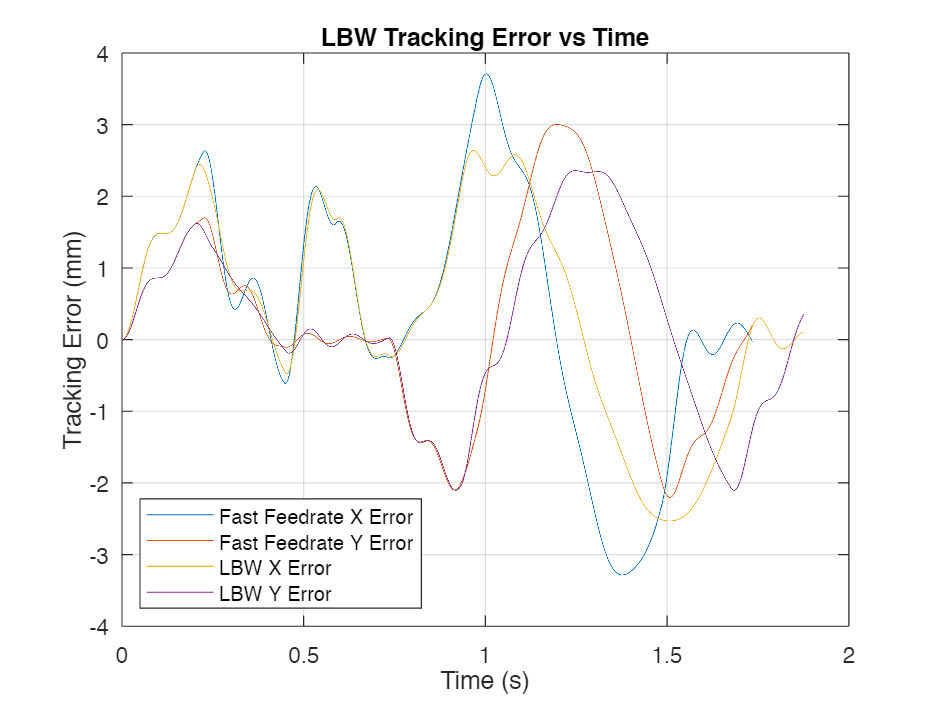


% F.2 Plot tracking error over time

time=simout(:,1);
position_command_x.fast=simout(:,2);
simulated_position_x.fast=simout(:,3);
position_command_y.fast=simout(:,4);
simulated_position_y.fast=simout(:,5);

tracking_error_x.fast=position_command_x.fast-simulated_position_x.fast;
tracking_error_y.fast=position_command_y.fast-simulated_position_y.fast;

figure()
plot(time,tracking_error_x.fast);
hold on;
plot(time, tracking_error_y.fast);
hold on;
plot(time_lbw,tracking_error_x.lbw);
hold on;
plot(time_lbw, tracking_error_y.lbw);
hold on;
hold off;
xlabel("Time (s)");
ylabel("Tracking Error (mm)");
title("LBW Tracking Error vs Time");
grid on;
legend("Fast Feedrate X Error", "Fast Feedrate Y Error", "LBW X Error", "LBW Y Error", Location="southwest");

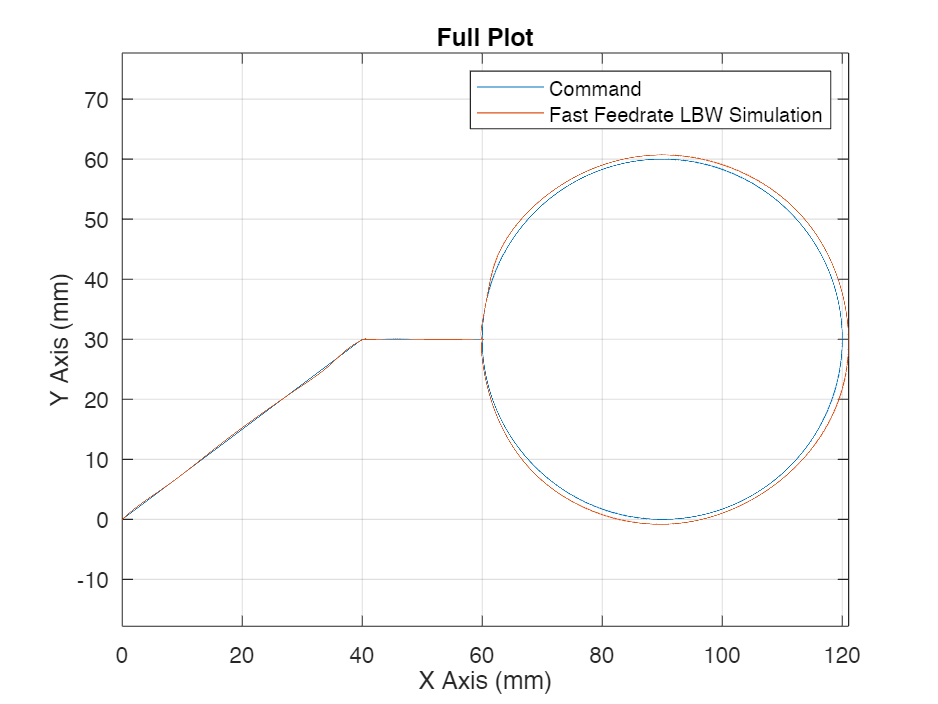



%Full Plot
plot(position_command_x.lbw,position_command_y.lbw);    %LBW x and y traj
hold on;
plot(simulated_position_x.fast, simulated_position_y.fast); %LBW x and y sim
hold off;
axis equal;
xlabel("X Axis (mm)");
ylabel("Y Axis (mm)");
grid on;
legend("Command", "Fast Feedrate LBW Simulation");
title("Full Plot");

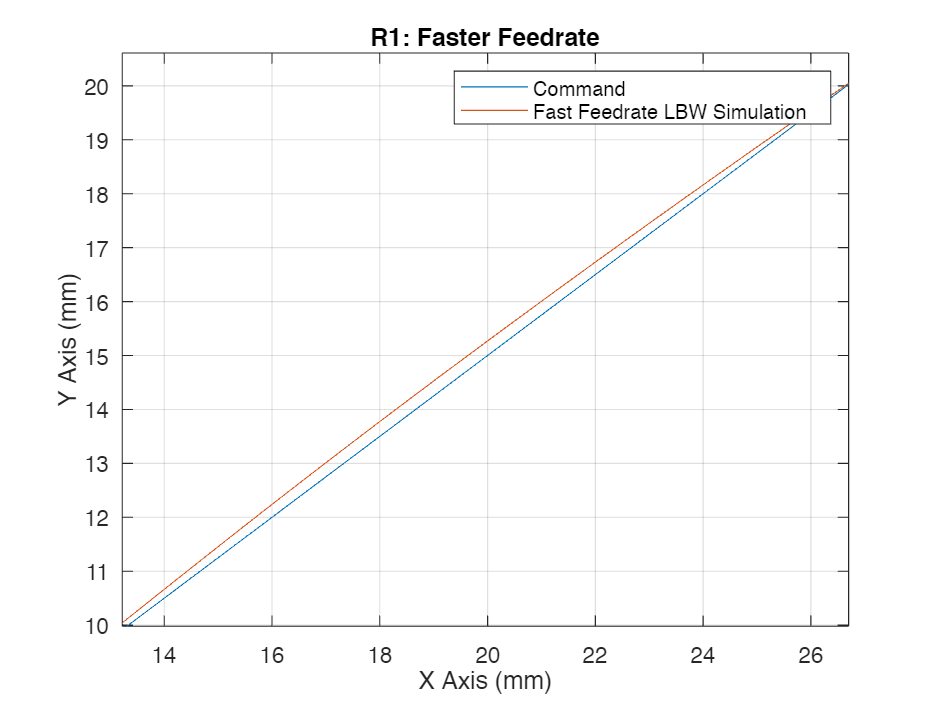

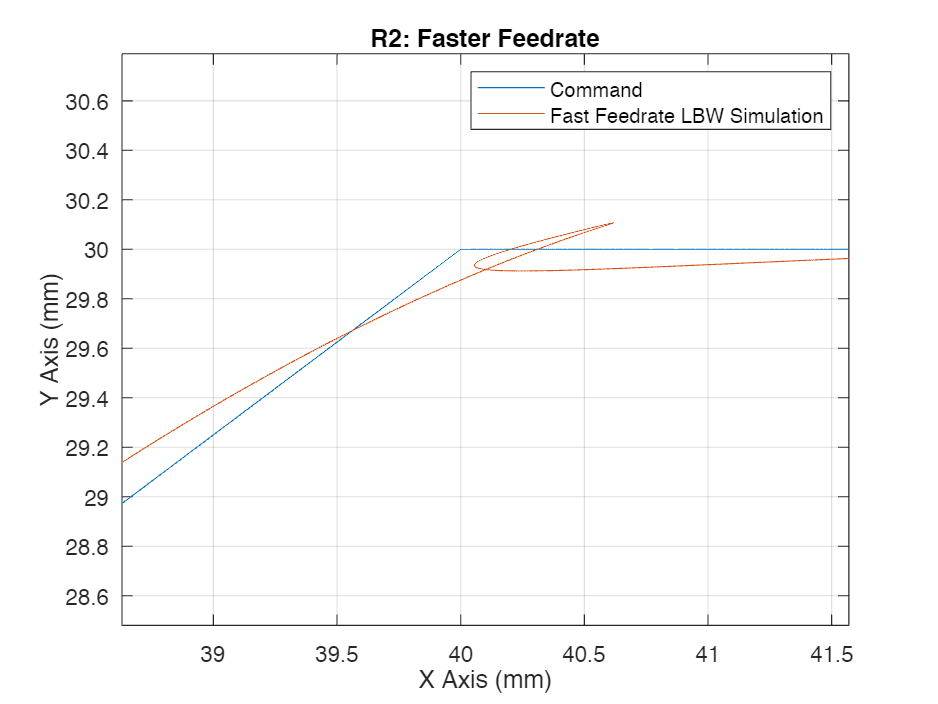

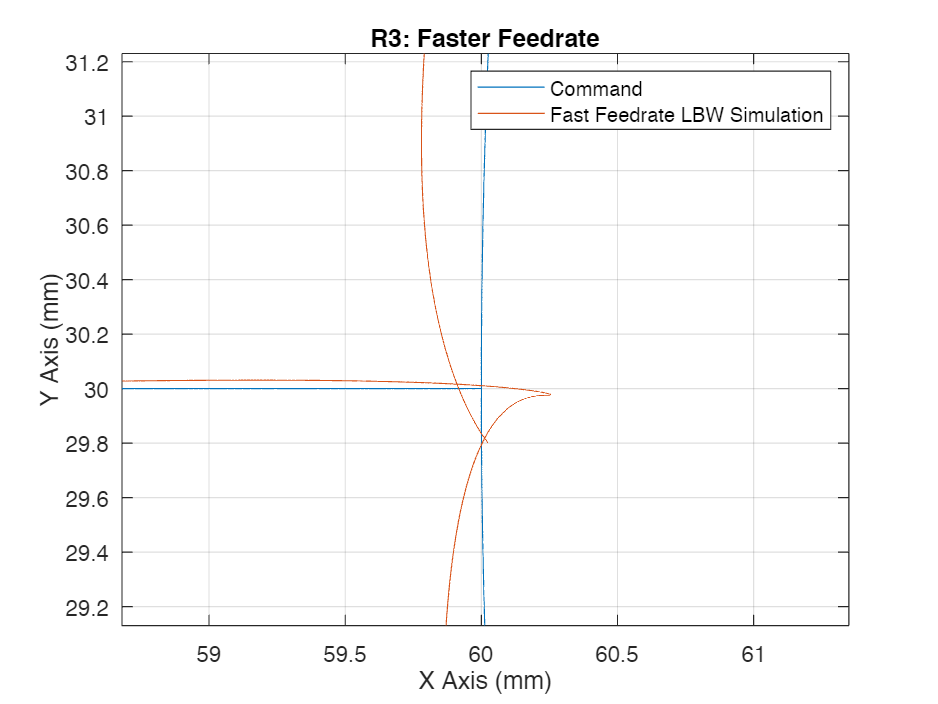

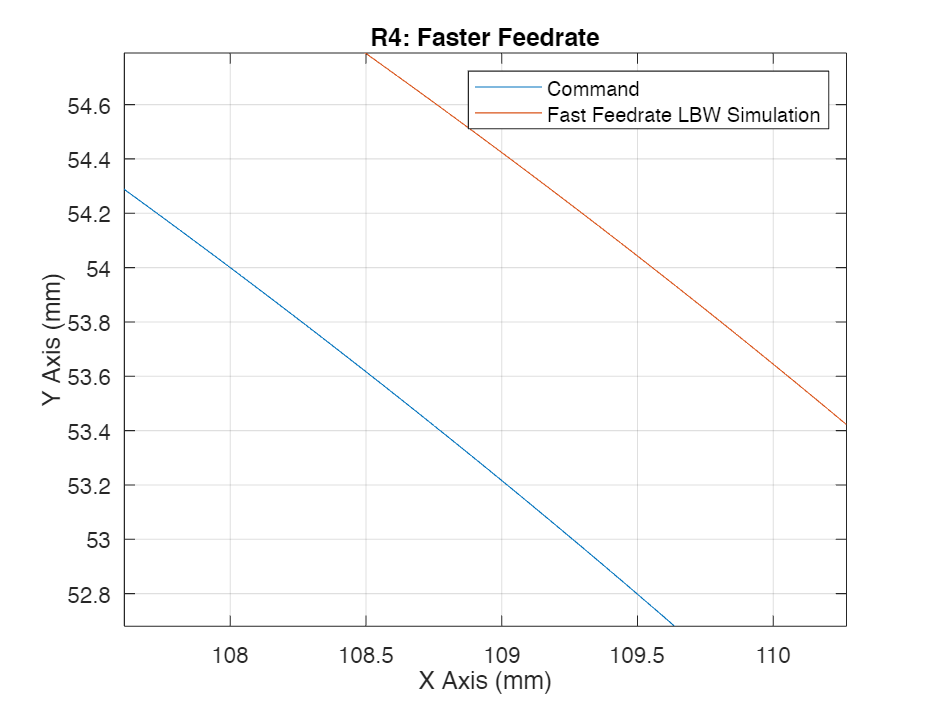


%X and Y limits for R1-R4
xlims=[13.22, 26.70 ; 38.63, 41.57 ; 58.68, 61.35; 107.61, 110.27]; 
ylims=[9.98, 20.61; 28.48, 30.79; 29.13, 31.23; 52.68, 54.79];



%position command indep of controller config
for i=1:4
    
    figure();
    plot(position_command_x.lbw,position_command_y.lbw);    %LBW x and y traj
    hold on;
    plot(simulated_position_x.fast, simulated_position_y.fast); %LBW x and y sim
    hold off;
    axis equal;
    xlabel("X Axis (mm)");
    ylabel("Y Axis (mm)");
    grid on;
    legend("Command", "Fast Feedrate LBW Simulation");
    xlim(xlims(i,:));
    ylim(ylims(i,:));
    title(strcat("R", num2str(i), ": Faster Feedrate"));
end

% %Part G
% defaultCoords=readtable("C:\Users\Lachlan Reynolds\Downloads\Default.csv", VariableNamingRule="preserve");
% 
% time_default=defaultCoords.Name/1000;
% traj_x=defaultCoords.X_Traj;
% traj_y=defaultCoords.Y_Traj;
% 
% actual_x=defaultCoords.X_ActPos;
% actual_y=defaultCoords.Y_ActPos;
% 
% tracking_error_x.experimental=traj_x-actual_x;
% tracking_error_y.experimental=traj_y-actual_y;
% 
% 
% plot(time_default,tracking_error_x.experimental);
% hold on;
% plot(time_default,tracking_error_y.experimental);
% hold on;
% plot(time_lbw, tracking_error_x.lbw);
% hold on;
% plot(time_lbw, tracking_error_y.lbw);
% hold off; 
% xlabel("Time (s)");
% ylabel("Tracking Error (mm)");
% title("Experimental LBW Tracking Error vs Time");
% grid on;
% legend("Experimental X", "Experimental Y", "LBW Simulated X Error", "LBW Simulated Y", Location="best");
% xlim([0 2]);
% 
% 
% 
% %X and Y limits for R1-R4
% xlims=[0, 120 ; 13.22, 26.70 ; 38.63, 41.57 ; 58.68, 61.35; 107.61, 110.27]; 
% ylims=[0, 70; 9.98, 20.61; 28.48, 30.79; 29.13, 31.23; 52.68, 54.79];
% 
% 
% 
% %position command indep of controller config
% for i=1:5
% 
%     figure();
%     plot(traj_x,traj_y);
%     hold on;
%     plot(actual_x,actual_y);
%     hold on;
%     plot(simulated_position_x.lbw,simulated_position_y.lbw);
%     hold off;
%     axis equal;
%     xlabel("X Axis (mm)");
%     ylabel("Y Axis (mm)");
%     grid on;
%     legend("Command", "Experimental Position", "Simulation Position");
% 
% 
%     if i==1
%         title("Full Plot: Experiment vs LBW Simulation")
%     else
%         title(strcat("R", num2str(i-1), ": Experiment vs LBW Simulation"));
%     end
% 
%     xlim(xlims(i,:));
%     ylim(ylims(i,:));
% 
% end
% 



toc

Elapsed time is 30.783785 seconds.


function O=ol_controller_design(G, p1, crossover_hz, PM)

Gol=G;

% Lead Lag 
crossover_freq=crossover_hz*2*pi;
[C,K, mag, phase, alpha, T]=ol_lead_lag_controller(Gol, crossover_freq, PM,p1);

O.K=K;
O.Magnitude=mag;
O.Phase=phase;
O.Alpha=alpha;
O.T=T;

% Cascaded Integrator
Ki=crossover_freq/10;
num_I=[1 Ki];
den_I=[1 0];
I=tf(num_I, den_I);

LLI=C*I;
O.LLI=LLI;
end


function l = createTrapezoidalTraj(L, fs, fe, F, Ti, A, D)

    % Author: Lal Deger, 2023.
    % L  - length of path, mm
    % fs - starting speed
    % fe - ending speed
    % F  - desired feedrate, mm/s
    % Ti - sampling time/interpolation period, s
    % A  - max acceleration, mm/s^2
    % D  -  max deceleration, mm/s^2

    L1 = (F^2 - fs^2) / (2 * A);
    L3 = (fe^2 - F^2) / (2 * D);
    L2 = L - L1 - L3;
    
    if L2 > 0 
        % estimate time
        T1 = 2 * L1 / (fs + F);
        T2 = L2 / F;
        T3 = 2 * L3 / (fe + F);
    
        % # of steps
        N1 = ceil(T1 / Ti);
        N2 = ceil(T2 / Ti);
        N3 = ceil(T3 / Ti);
    
        % re-eval times
        T1n = N1 * Ti;
        T2n = N2 * Ti;
        T3n = N3 * Ti;
    
        % re-eval speeds
        fcn = (2 * L - fs * T1n - fe * T3n) / (T1n + 2 * T2n + T3n);
        An = (fcn - fs) / T1n;
        Dn = (fe - fcn) / T3n; 
    
        % compute traj
        tau_1 = Ti * (0:N1);
        tau_2 = Ti * (1:N2);
        tau_3 = Ti * (1:N3);
        l1 = fs * tau_1 + 1/2 * An * tau_1 .^ 2;
        l1n = l1(end);
        l2 = l1n + fcn * tau_2;
        l2n = l2(end);
        l3 = l2n + fcn * tau_3 + 1/2 * Dn * tau_3 .^ 2;
        l = horzcat(l1, l2,  l3);
    else 
        % override desired feedrate 
        fcm = sqrt((2 * A * D * L - (fe^2 * A - fs^2 * D)) / (D - A));
    
        T1 = (fcm - fs) / A;
        T3 = (fe - fcm) / D;
        N1 = ceil(T1 / Ti);
        N3 = ceil(T3 / Ti);
    
        T1n = N1 * Ti;
        T3n = N3 * Ti;
    
        % re-eval speeds
        fcnm = (2 * L - fs * T1n - fe * T3n) / (T1n + T3n);
        An = (fcnm - fs) / T1n;
        Dn = (fe - fcnm) / T3n; 
    
        % compute traj
        tau_1 = Ti * (0:N1);
        tau_3 = Ti * (1:N3);
        l1 = fs * tau_1 + 1/2 * An * tau_1 .^ 2;
        l1n = l1(end);
        l3 = l1n + fcnm * tau_3 + 1/2 * Dn * tau_3 .^ 2;
        l = horzcat(l1, l3);
    end

end

function [C, K, mag, phase, alpha, T]=ol_lead_lag_controller(G, crossover, PM, p1)

crossover_freq=crossover;
desired_PM=PM;

phi_m=180*(-pi/2-atan(crossover_freq/p1))/pi;
phase_to_add=desired_PM-(180+phi_m);
phase_to_add=phase_to_add*pi/180;           %in rad now

alpha=(1+sin(phase_to_add))/(1-sin((phase_to_add)));

T=1/(crossover_freq*sqrt(alpha));

K=1; %initially set to 1

%determine transfer
num_LL=K*[alpha*T 1];
den_LL=[T 1];
C=tf(num_LL, den_LL);                           
[mag, ~]=bode(C*G, crossover_freq);
K=1/mag; %determine K

%re do transfer func with new K
num_LL=K*[alpha*T 1];
den_LL=[T 1];
C=tf(num_LL, den_LL);                           
[mag, phase]=bode(C*G, crossover_freq);


end


function [D_d, D_c]=controller_description(closedloop_axis_bandwidth_domain, G_axis_c, Ti)


RT=[0.1 0.9];

Gcl_c=closedloop_axis_bandwidth_domain;
%S Domain

S=stepinfo(Gcl_c, 'RiseTimeLimits', RT);
D_c.Overshoot=S.Overshoot;
D_c.Risetime=S.RiseTime;
D_c.Poles=pole(Gcl_c);
D_c.Zeros=zero(Gcl_c);
D_c.Bandwidth=bandwidth(Gcl_c);


%Zdomain

G_axis_d=c2d(G_axis_c, Ti, 'zoh');
LLI_bw_d = c2d(Gcl_c, Ti, 'tustin');
ol_x_lbw_d = minreal(LLI_bw_d * G_axis_d);
cl_x_lbw_d = feedback(ol_x_lbw_d, 1);


S=stepinfo(cl_x_lbw_d, 'RiseTimeLimits', RT);
D_d.Overshoot=S.Overshoot;
D_d.Risetime=S.RiseTime;
D_d.Poles=pole(cl_x_lbw_d);
D_d.Zeros=zero(cl_x_lbw_d);
D_d.Bandwidth=bandwidth(cl_x_lbw_d);
D_d.LTI=LLI_bw_d;
end
